Atviteli fuggvenykent adjuk meg

num = [1 1];
den= [1 2 2];
W=tf(num,den)

W =
 
      s + 1
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.



Az elozo atviteli fgv-t Allapotegyenletes leirassa alakitjuk

sys =ss(W)

sys =
 
  A = 
       x1  x2
   x1  -2  -2
   x2   1   0
 
  B = 
       u1
   x1   2
   x2   0
 
  C = 
        x1   x2
   y1  0.5  0.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



A matrix sajatertekei es az atviteli nevezo gyokei

nevezo_gyokei=roots(W.den{1})

nevezo_gyokei =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


sajatertek = eig(sys.A)

sajatertek =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


Vizsgalat - Egysegugras- es impulzus-valasz

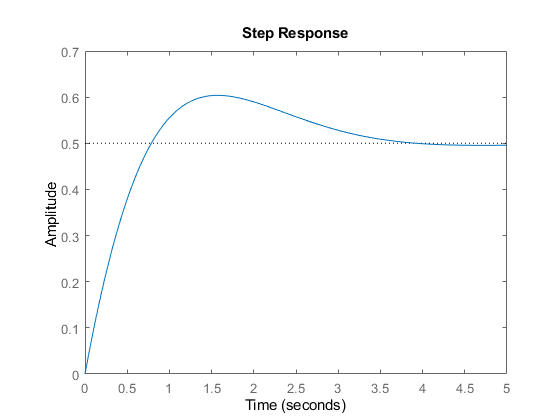

step(W)

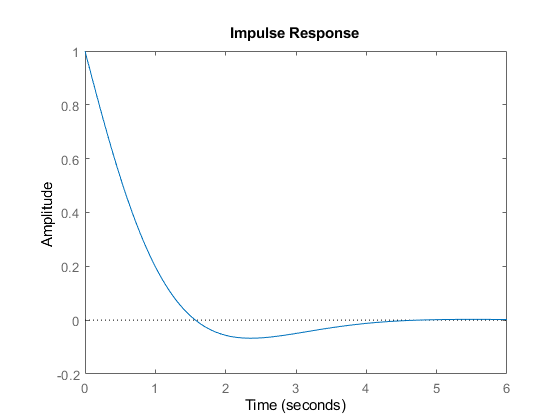

impulse(sys)

Polus-Zerus

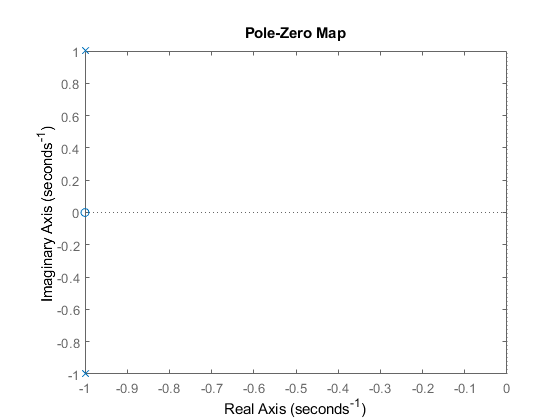

pzmap(W)

Bode-diagram

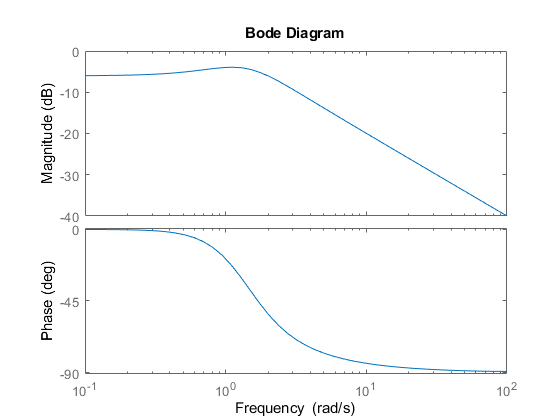

bode(sys)

Nyquist-diagram

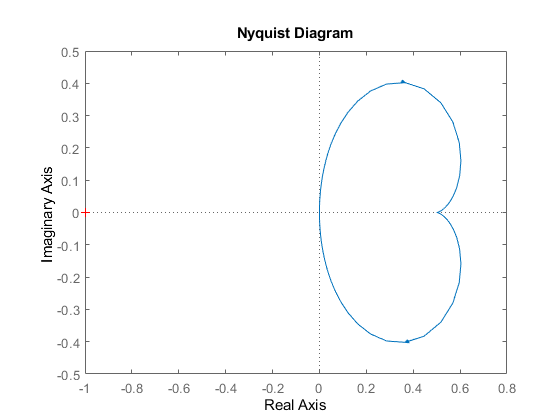

nyquist(W)

clear;
clc;

Egytarolos rendszer

T=3; W = tf(1,[T 1]);

Polusa a -(1/T) -ben

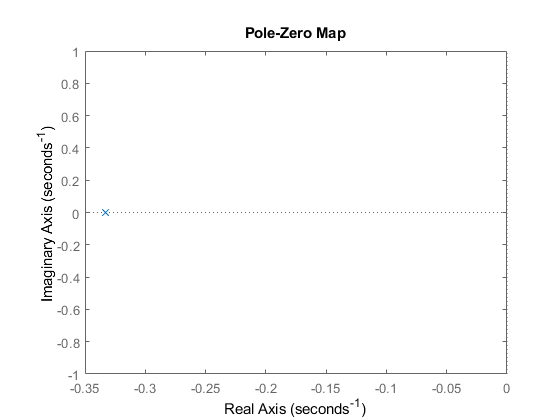

pzmap(W)

Polus 0 kozel lassuak

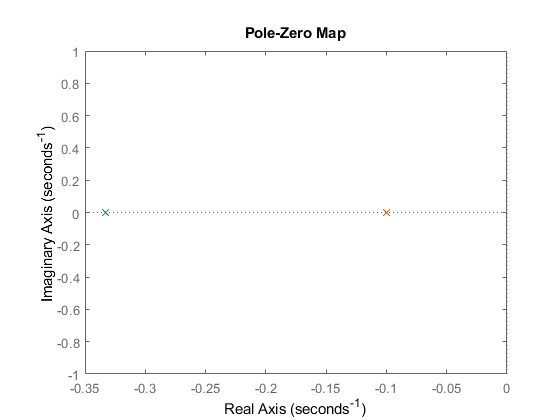

T2=10; W2=tf(1, [T2 1]);
pzmap(W,W2)

Step fgv - lassab??

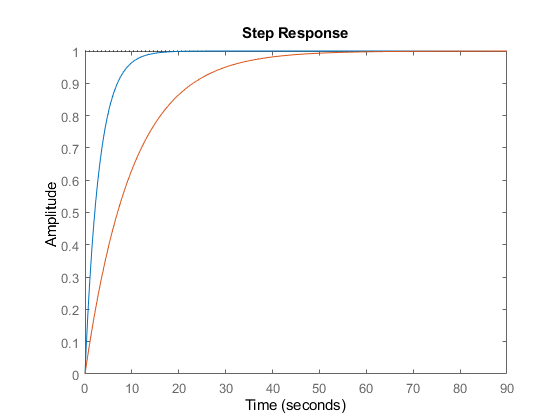

step(W,W2);

Ha a jobbklikk nem akarja

%ltiview(W,W2)%

Masodfoku rendszer

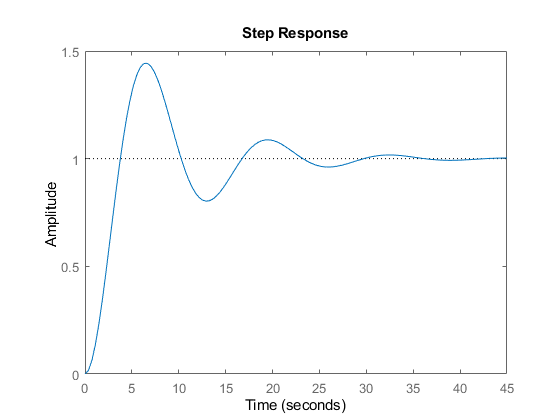

T=2; xi=0.25;W3=tf(1, [T^2, 2*xi*T, 1]);
step(W3);

%ltiview(W3)%
w0=1/T; 
Tm=pi/(w0*sqrt(1-xi^2))

Tm = 6.4892

dv=exp(-pi*xi/sqrt(1-xi^2))

dv = 0.4443

Csillapitas es tulloves kapcsolata

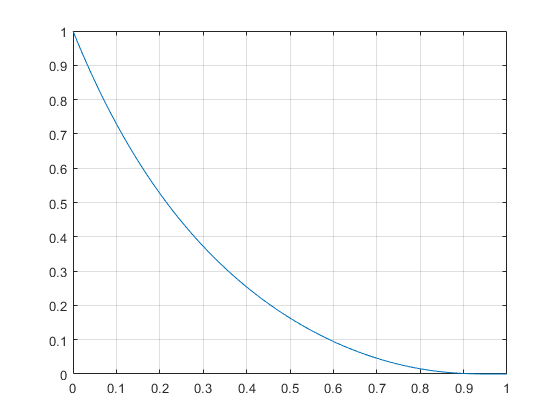

xi=0:0.01:1;
dv=exp(-pi*xi./sqrt(1-xi.^2)); % Pontokra figyelni! %
plot(xi,dv);grid on; % 0.7 -> 0.05 tullovest szeretjuk %